# Lab Session 1

**Multibody System Dynamics**

This session deals with kinematics of multibody systems. We will work on two fundamental aspects:

- **The position problem**

- **The inverse kinematics problem**

Before we start, let's clean up the workspace

clearvars
close all % windows

and setup the current directory

cd(fileparts(matlab.desktop.editor.getActiveFilename))
addpath("../models")
addpath("../source")

### Double Pendulum

First, let's generate a M`odel` of a double pendulum. Here we define the properties of the **bodies**, **joints** and **coordinates** in the model.

model = DoublePendulum();

*Do you know how many bodies, joints, and degrees of freedom this model has?*

### System

The S`ystem` is the data structure of the multibody system formulation. It contains the generalized coordinates, and velocities, the constraints information.

system = System(model);
system.initSystem();

After modifying the system the model must be updated.

system.updateModel();

### Model Viewer

A model viewer can be used to disply the bodies geometry.

viewer = Viewer(model);

It is possible to change the size of the window:

viewer.axes.XLim = [-2,+2];
viewer.axes.YLim = [-2,+2];

After modifying the model, the view can be updated using:

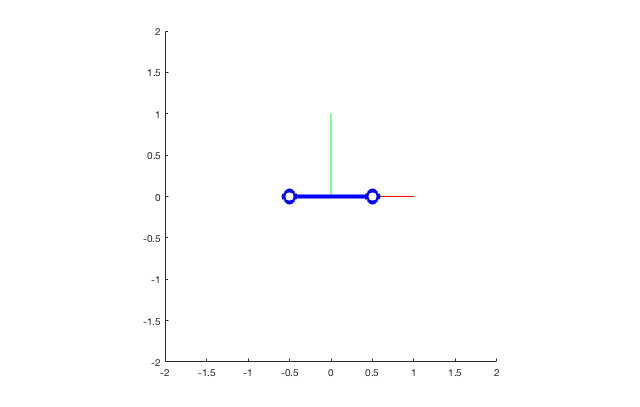

viewer.update();

## The Position Problem

The multibody system has a set of $m$ dependent coordinates ${\bf q}_{(m \times 1)}$ with a set of $r$ constraint equations


$${\bf \Phi} ({\bf q}) = {\bf 0}_{(r \times 1)}$$


Then, a set of $n = m - r$ independent coordinates ${\bf s}({\bf q})_{(n \times 1)}$ parametrizes the motion of the constraint system.

The position problem aims at finding the value of the dependent coordinates ${\bf q}$ that satysfy the constraint equations ${\bf \Phi} ({\bf q}) = {\bf 0}$. Additionally, an initial value for the dependent coordinates ${\bf s (q)} = {\bf s}_0$ can also be specified.

Therefore, we need to solve the following nonlinear equation:


$${\bf \beta (q)} = \left[\matrix{ {\bf \Phi (q)} \cr {\bf s (q)} - {\bf s}_0 } \right] = {\bf 0}_{(m \times 1)}$$


### Newton–Rapson Algorithm

To solve the nonlinear equation ${\bf \beta(q) = 0}$ using the Newton–Rapson algorithm, we need a linear approximation of the constraints equation about a configuration ${\bf q}_0$


$${\bf \beta (q)} \approx {\bf \beta} ({\bf q}_0) + {\bf J}({\bf q}_0) ({\bf q} - {\bf q}_0)$$


where ${\bf J(q)}_{(m \times m)}$ is the Jacobian matrix of the coordinate transformation. Then, if we set ${\bf \beta(q) = 0}$, the following iterative algorithm can be defined


$${\bf q}_{(k+1)} = {\bf q}_{(k)} - {\bf J}({\bf q}_{(k)})^{-1} {\bf \beta} ({\bf q}_{(k)})$$


Therefore, starting from a configuration ${\bf q}_0$, we can perform iterations until we find the configuration ${\bf q}$ that satisfies the nonlienar equation ${\bf \beta(q) = 0}$ under a certain tolerance $\| {\bf q}_{(k+1)} - {\bf q}_{(k)}\| < \varepsilon$.

### Exercise

Write a function to solve the possition problem using the **Newton–Rapson algorithm**. You must specify the desired value for the independent coordinates ${\bf s}_0$ and the starting point for the dependent coordinates ${\bf q}_0$.

Note: the following function must be called before you use the constraint position `conPos` and independent coordinates `cooInd`, as well as the Jacobian matrices `conJac` and `indJac`.

% system.updateSysPosition();
% system.updateJacobians();

**Solution:**

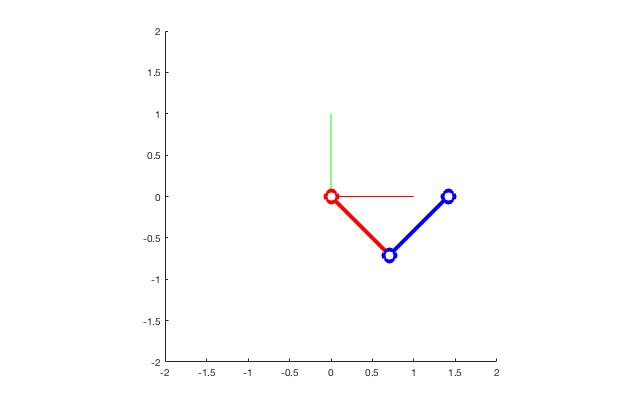

qInd0 = [-pi/4; pi/2];
tol = 1E-5;
res = tol;

while res >= tol
    
    system.updateSysPosition();
    system.updateJacobians();
    
    b = [system.cooInd - qInd0; system.conPos];
    J = [system.indJac; system.conJac];
    
    step = - (J \ b);
    res = norm(step);
    
    system.cooDep = system.cooDep + step;
    system.updateModel();
    viewer.update();
end